%% Parámetros del potencial
alpha = 1;
beta  = 0;
delta = (2/3)^(2/3);

%% Malla en [-1,1] × [-1,1]
N = 400;
x = linspace(-1, 1, N);
y = linspace(-1, 1, N);
[X, Y] = meshgrid(x, y);

%% Cálculo del potencial
V = X.^4 - alpha.*X.^2 - delta.*X + Y.^4 - Y.^2 + beta.*X.^2.*Y.^2;


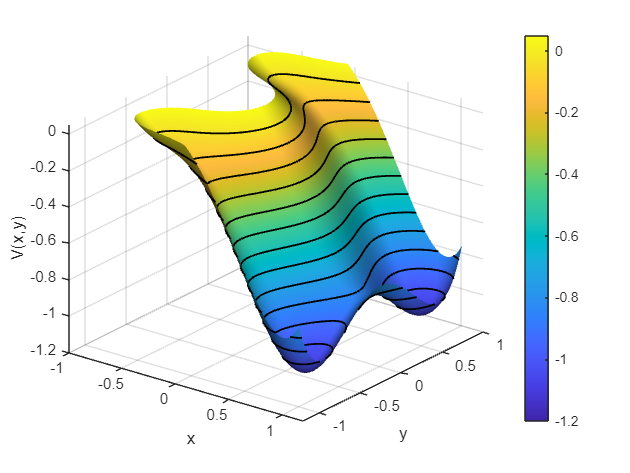


%% Figura combinada: superficie con sombra proyectada (con base coloreada)
figure('Name','Superficie con Sombra y Base','NumberTitle','off')

% Superficie 3D principal
surf(X, Y, V, 'FaceAlpha', 1.0, 'EdgeColor', 'none');
colormap(parula);
shading interp;
hold on;

% Curvas de nivel sobre la superficie y sobre la sombra
contour3(X, Y, V, 20, 'k', 'LineWidth', 1.2);

% Ejes y vista
xlabel('x'); ylabel('y'); zlabel('V(x,y)');
% title(sprintf('V(x,y)'));
axis([-1 1.2 -1.2 1 -1.2 0.05]);
view(45,30);
grid on;

% Luces y material
material dull;
lighting gouraud;
camlight headlight;
caxis([-1.2, 0.05]);
colorbar;
hold off;

colorbar;

view([37.45 26.26])

% 
% view([31.162 59.919])




%% Curvas de nivel con fondo blanco y líneas coloreadas
figure('Name','Curvas de Nivel','NumberTitle','off')
set(gcf, 'Color', 'w'); % Fondo blanco
[~, h] = contour(X, Y, V, 20); % 20 niveles
colormap(parula); % Escala de color para las líneas
h.LineWidth = 1.2; % Grosor de las líneas
colorbar;
caxis([-0.6, 0.05]);
axis equal; axis([-1 1 -1 1]);
xlabel('x'); ylabel('y');
% title('Curvas de Nivel de V(x,y)');
box on;



